# DRTS Mini project: Canbus

This is documentation of mini project from the course Distributed Real-Time Systems.

## Assignment task 1: 

### - Create a DNC/RTC arrival-model of the periodic external traffic sources of the in-car network (choose arrival curve types and determine parameters)

Of the periodic external traffic sources there are four wheel sensors and one ESP sensor. The arrival curve is chosen to be of the affine type. The parameters of the external sources are defined in the script below. The periodic external traffic sources will be defined in the following order. 

- Arrival curve for one wheel sensor

- Arrival curve for the 4 wheel sensors combined

- Arrival curve for ESP 

- Combination of all periodic sources in one arrival curve

clc;clear;close all;

BW = 1*10^3; % [bpms] Serialization speed ms = miliseconds

% ======================= Wheel sensor parameters =======================
N_W = 4;		% Amount of wheel sensors   
p_W = 20;		% Amount of bits per sensor per period
O = 0;			% Overhead
T = 10;			% Transfer period for both wheel sensor and ESP [ms]

n = 1;			% Amount of sensor packets in each dataframe (CAN packet)
k_W = p_W*n+O;	% Bits per packet
tau = 0;		% jitter

% Arrival curve - One wheel sensor:
r_W = k_W/(n*T);					% Rate
b_W = k_W * (tau/T + 1);			% Burst
arr_W = rtccurve([0, b_W, r_W]);	% Arrival curve definition 


The arrival curve of the one wheel sensor is plotted below in Figure 1

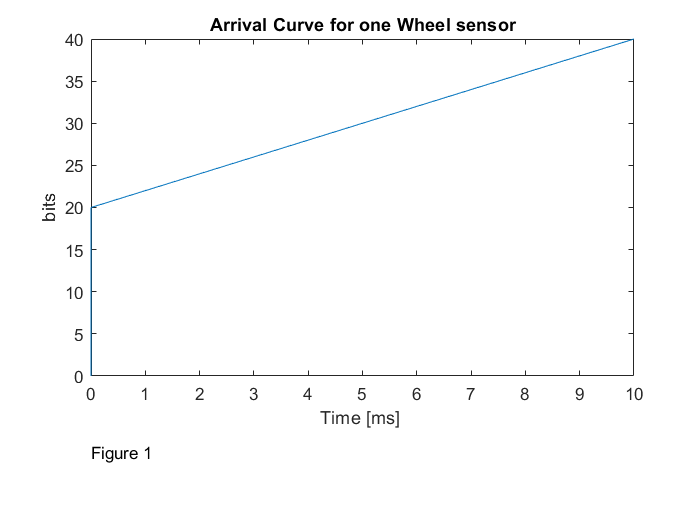

figure(1)
rtcplot(arr_W,T)
title('Arrival Curve for one Wheel sensor')
xlab = sprintf('Time [ms] \n\n\n\n');
xlabel(xlab)
text(0,-9,'Figure 1')
ylabel('bits')

The 4 wheel sensors are joined into one arrival curve

% Arrival curve - All wheel sensors
r_W_all = N_W*r_W;								% Rate
b_W_all = N_W*b_W;								% Burst
arr_W_all = rtccurve([0, b_W_all, r_W_all]);	% Arrival curve definition 

The arrival curve of the 4 joined wheel sensor is plotted below in Figure 2

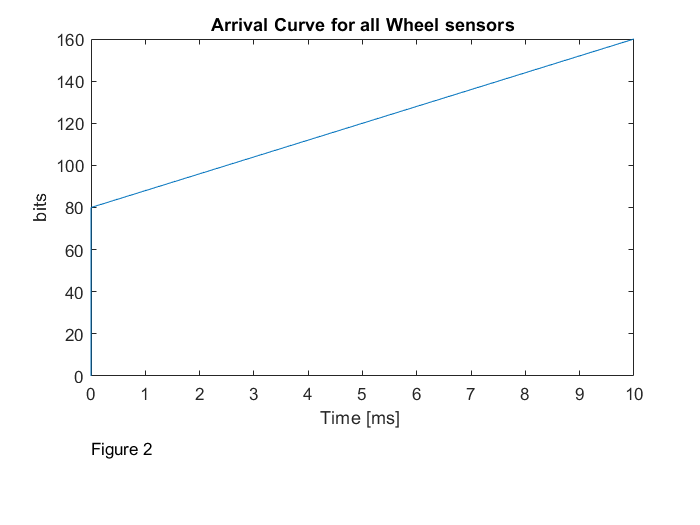

figure(2)
rtcplot(arr_W_all,T)
title('Arrival Curve for all Wheel sensors')
xlabel(xlab)
text(0,-34,"Figure 2")
ylabel('bits')

Next up is the arrival curve of the ESP sensor, it is defined as follows

% Arrival curve - ESP sensor
p_ESP = 8;			% Amount of bits per sensor per period
k_ESP = p_ESP+O;	% Bits per period, including overhead

% Arrival:	
r_ESP = k_ESP/(n*T);					% Rate
b_ESP = k_ESP * (tau/T + 1);			% Burst
arr_ESP = rtccurve([0, b_ESP, r_ESP]);	% Arrival curve definition 

The arrival curve of the ESP sensor is plotted below in Figure 3

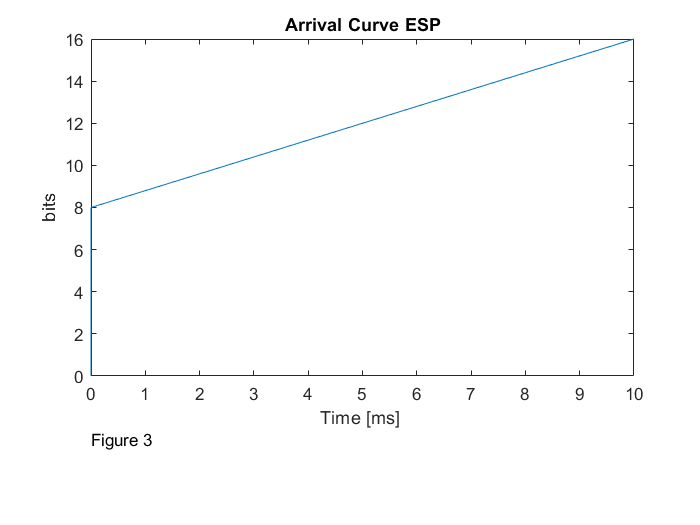

figure(3)
rtcplot(arr_ESP,T)
title('Arrival Curve ESP')
xlabel(xlab)
text(0,-3,"Figure 3")
ylabel('bits') 

As a last resort, the 4 Wheel sensors and the ESP is combined to create one arrival for all periodic traffic sources.

% Combination of periodic arrival constraints:
r_per = r_W_all + r_ESP;	% All periodic rate
b_per = b_W_all + b_ESP;	% All periodic burst

The arrival curve of all periodic traffic sources is plotted below in Figure 4

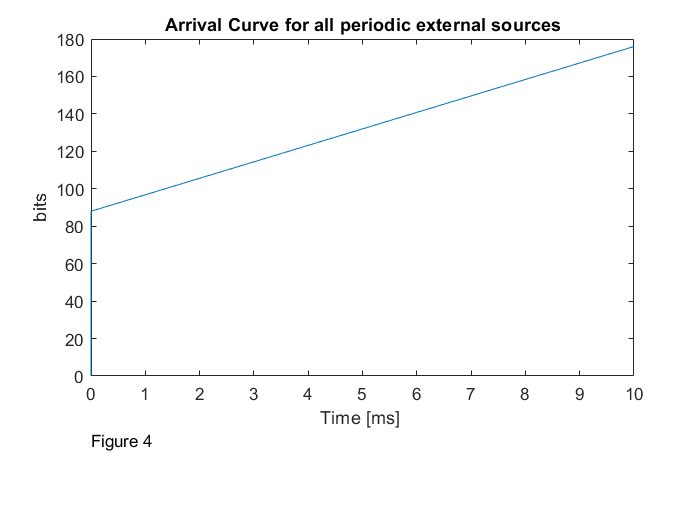

figure(4)
arr_per = rtccurve([0, b_per, r_per]);	 % Periodic sources arrival curve
rtcplot(arr_per, T)
title('Arrival Curve for all periodic external sources')
xlabel(xlab)
text(0,-34,"Figure 4")
ylabel('bits')

As seen in Figure 4, the burst is 88 corresponding to one packet from each periodic traffic source (4*20 + 8). The rate of the periodic sources is 8.8/ms, corresponding to the 88 bits/10 ms.

### - Create a DNC/RTC model for your communication network (Identify network elements, select curve types and parameters)

There is one network element i our communication network, nemely the CANbus interface. A service curve is defined.

Service curve rate is set a 5% lower than bandwidth to ensure we're not marginally stable.

% Service curves:
d = (n-1)*T; % Delay - 0 since we are not packing more than one sensor
serv = rtccurve([d, 0, BW*0.95]);

The service curve of the CANbus is plotted below in Figure 5

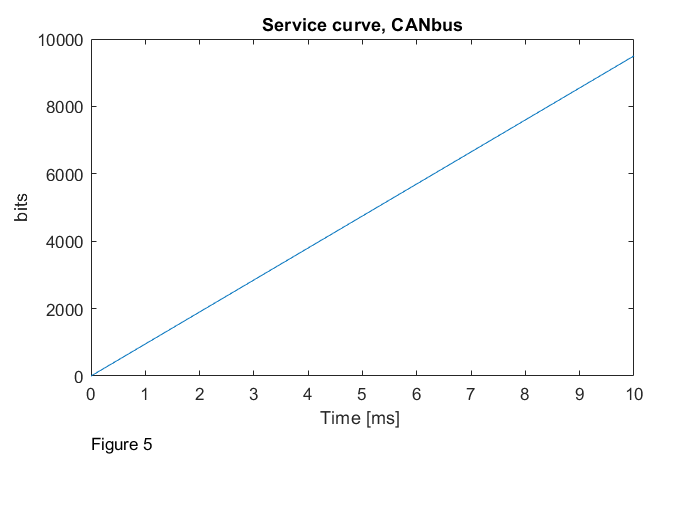

figure(5)
rtcplot(serv,T)
title('Service curve, CANbus')
xlabel(xlab)
text(0,-2000,"Figure 5")
ylabel('bits')

The service curve of the CANbus is not plotted with the arrival curve of the periodic traffic sources, along with the maximum backlog and delay. This can be seen below in Figure 6

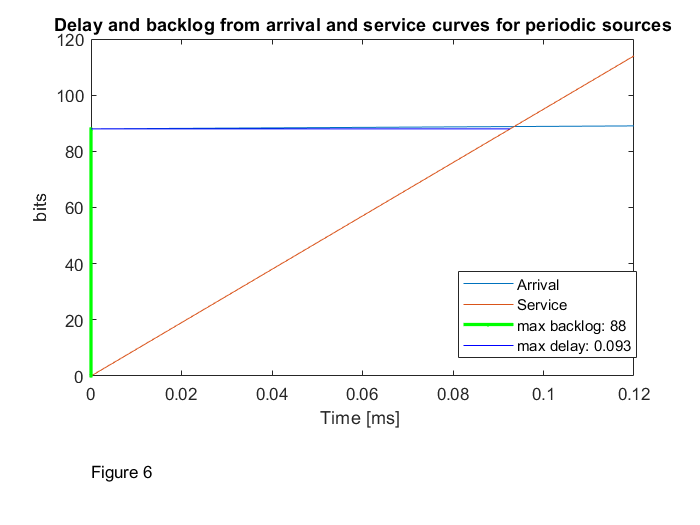

% Backlog and delay of periodic sources:
figure(6)
rtcplot(arr_per, 0.12) % Plot Arrival curve
hold on
rtcplot(serv) % Service curve
rtcplotv(arr_per,serv) % Backlog
rtcploth(arr_per,serv, 'b') % Delay
title('Delay and backlog from arrival and service curves for periodic sources')
xlabel(xlab), text(0,-34,"Figure 6")
ylabel('bits')

delay = rtch(arr_per,serv); backlog = rtcv(arr_per,serv);
str_delay = sprintf('max delay: %0.3f', delay);
str_backlog = sprintf('max backlog: %d', backlog);
legend('Arrival', 'Service', str_backlog, str_delay)

legend('Position',[0.65417,0.3177,0.25536,0.16548])

The maximum possible backlog is 88 bits, with a corresponding maximum delay of 0.093 ms

### - Guess initial parameters for token bucket filters (for the Poisson traffic sources) and include parameters in the DNC/RTC model.

% - Packet size is defined in task as 1400 bits
% - Average period is set to 30 ms (although its a poisson process)

% Rear Camera parameters
T_RC = 40;		% [ms]
p_RC = 1400;	% Packet size - Number of bits per packet

% Multimedia parameters
T_MM = 40;		% [ms]
p_MM = 1400;	% Packet size - Number of bits per packet

% Token bucket filter parameters - initial guesses
M_TB = 5;		% Bucket size - Burst parameter (random guess=
T_TB = 30;		% [ms] Token replenishment rate - Curve rate (faster than 40ms)



### - Determine arrival curves for outputs of token bucket filters and include in the DNC/RTC model.

% Arrival curve Rear Camera
r_RC = 1/T_TB * p_RC;
b_RC= p_RC * M_TB;
arr_RC = rtccurve([0, b_RC, r_RC]);

The arrival curve of the rear camera is plotted in Figure 7

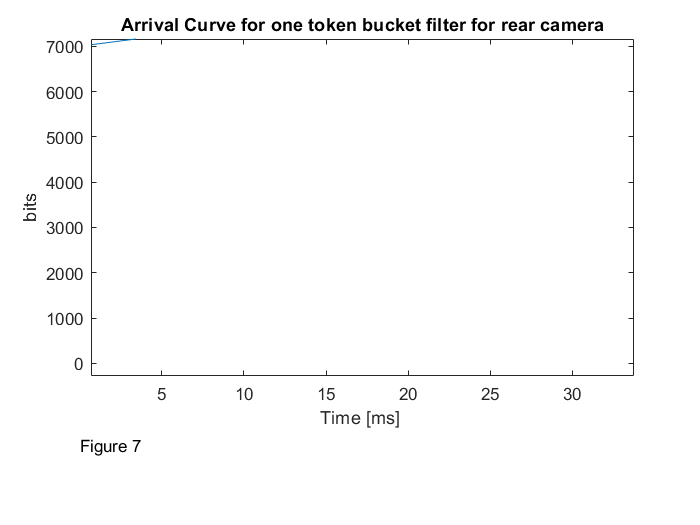

figure(7)
rtcplot(arr_RC, T_RC)
title('Arrival Curve for one token bucket filter for rear camera')
xlabel(xlab), text(0,-1800,"Figure 7")
ylabel('bits')

% Arrival curve Multi-media
r_MM = 1/T_TB * p_MM;
b_MM= p_MM * M_TB;
arr_MM = rtccurve([0, b_MM, r_MM]);

The arrival curve of the multi media is plotted in Figure 8

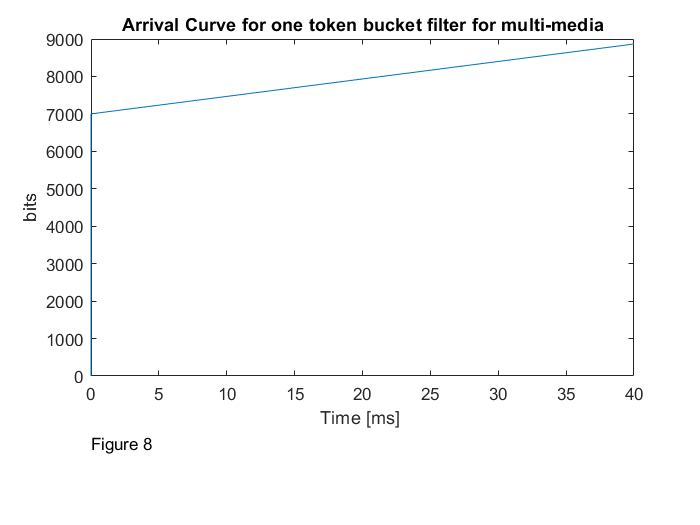

figure(8)
rtcplot(arr_MM, T_MM)
title('Arrival Curve for one token bucket filter for multi-media')
xlabel(xlab), text(0,-1800,"Figure 8")
ylabel('bits')

The arrival curves of the multi media and rear camera is combined into one arrival curve:

arr_TB_tot = rtcplus(arr_RC, arr_MM);

The combined arrival curves of the rear camera and multi media is plotted in Figure 9

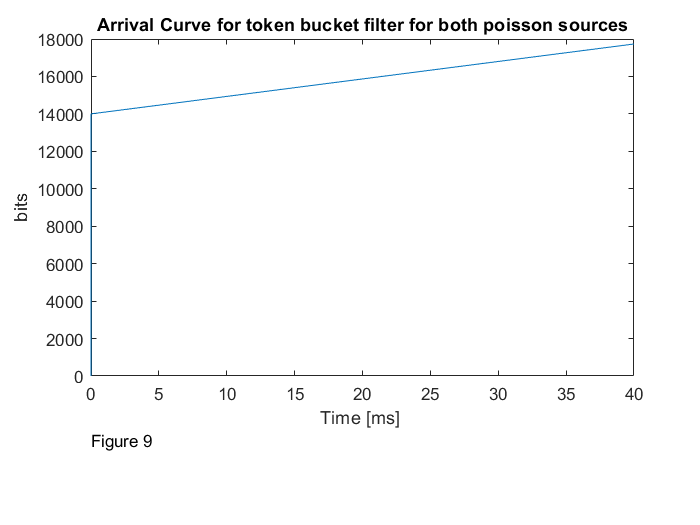

figure(9)
rtcplot(arr_TB_tot, T_MM)
title('Arrival Curve for token bucket filter for both poisson sources')
xlabel(xlab), text(0,-3400,"Figure 9")
ylabel('bits')

### - Compute max backlogs and max waiting times for all flows for the (non)deterministic part of the network

The arrival curves of both the periodic (Wheel sensor and ESP) and token bucket (Rear camera and multi media) sources are combined

% Arrival curve: All external network sources (periodic and poisson)
arr_all = rtcplus(arr_per, arr_TB_tot);


Backlog and delay is computed and plotted from combined arrival curve of all the sources along with the service curve of the CANbus network, in Figure 10

% Backlog and delay:
figure(10)
rtcplot(arr_all, 20) % Plot Arrival curve
hold on
rtcplot(serv) % Service curve
rtcplotv(arr_all,serv) % Backlog
rtcploth(arr_all,serv, 'b') % Delay
title('Delay and backlog from arrival and service curves of all external sources')
xlabel(xlab), text(0,-3400,"Figure 10")
ylabel('bits')

delay = rtch(arr_all,serv), backlog = rtcv(arr_all,serv)

delay = 14.8295

backlog = 14088

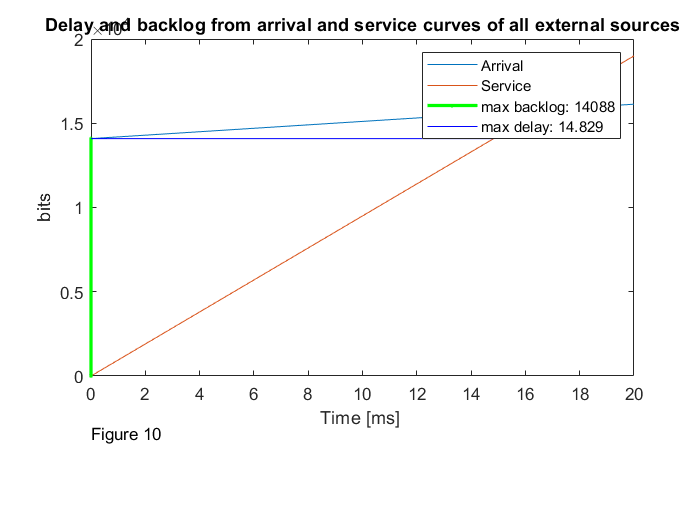

str_delay = sprintf('max delay: %0.3f', delay);
str_backlog = sprintf('max backlog: %d', backlog);
legend('Arrival', 'Service', str_backlog, str_delay)

figure(11)
subplot(3,1,1)

rtcplot(arr_per, T)
title(['' ...
	'Arrival Curve for all periodic external sources'])
xlabel('time [ms]')
ylabel('bits')

subplot(3,1,2)
rtcplot(arr_TB_tot, T_MM)
title('Arrival Curve for token bucket filter for both poisson sources')
xlabel('time [ms]')
ylabel('bits')

subplot(3,1,3)
rtcplot(arr_all, 20) % Plot Arrival curve
hold on
rtcplot(serv) % Service curve
rtcplotv(arr_all,serv) % Backlog
rtcploth(arr_all,serv, 'b') % Delay
title('Delay and backlog from arrival and service curves of all external sources')
xlabel('time [ms]')
ylabel('bits')

delay = rtch(arr_all,serv), backlog = rtcv(arr_all,serv)

delay = 14.8295

backlog = 14088

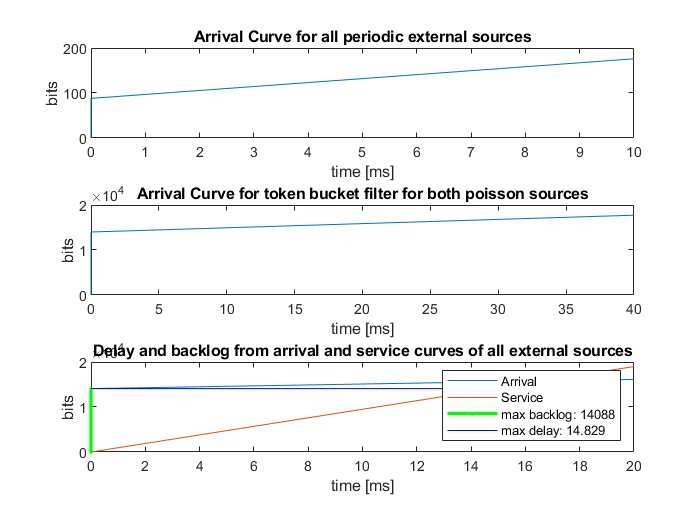

str_delay = sprintf('max delay: %0.3f', delay);
str_backlog = sprintf('max backlog: %d', backlog);
legend('Arrival', 'Service', str_backlog, str_delay)

## Assignment task 3

#### Select a suitable queueing model for Token Bucket input queues

To accommodate a finite queue (buffer) length, the M/M/1/L is chosen as a probabilistic model for the Token Bucket Filter.

#### Compute mean queue lengths, mean waiting times and packet drop probabilities for input queues.

The M/M/1/L queue can be characterised in steady state based on their parameters $\lambda$(arrival intensity), $\mu$(service intensity), and a utilisation parameter $\rho =\frac{\lambda }{\mu }\;$

The token bucket filters implemented in the simulation have the same parameters:


$$\begin{array}{l}
\lambda =\frac{1}{40\;\textrm{ms}}\;\\
\mu =\frac{1}{30\;\textrm{ms}}\\
\rho =\frac{\lambda }{\mu \;}=\frac{30}{40}=0\ldotp 75\\

\end{array}$$


lambda = 1/(T_RC*1e-3);	mu = 1/(T_TB*1e-3);
rho = lambda/mu;
L = 6;	% Queue size

The mean queue length can be obtained by the expression


$$\begin{array}{l}
E\left\lbrack Q\right\rbrack =\frac{\rho }{\left(1-\rho^{L+1} \right)\left(1-\rho \right)}\\
\;
\end{array}$$


EQ = rho / ( (1-rho^(L+1)) * (1-rho) )

EQ = 3.4621

The mean waiting time can be obtained by the expression

$E\left\lbrack T\right\rbrack =\frac{1}{\mu }\left(E\left\lbrack Q\right\rbrack +1\right)$ % the one is here as the new arrival to show the delay..

ET = (1/mu) * (EQ + 1) 

ET = 0.1339

The probability of package loss can be obtained by the expression


$$P_{\textrm{Loss}} =\frac{\rho^L -\rho^{L+1} }{1-\rho^{L+1} }$$


P_loss = (rho^L-rho^(L+1)) / (1-rho^(L+1))

P_loss = 0.0513